%  
x=1:7

x =      1     2     3     4     5     6     7


xn=-2:4

xn =     -2    -1     0     1     2     3     4



% using conv_i function
[y,yn]=sigshift(x,xn,2) % left shift

y =      1     2     3     4     5     6     7


yn =     -4    -3    -2    -1     0     1     2


% w=randn(1,length(xn));
% [y,n]=sigadd(y,yn,w,yn);
[xf,xnf]=sigfold(x,xn) % always folding signal before using the conv_i function to get the expected result

xf =      7     6     5     4     3     2     1


xnf =     -4    -3    -2    -1     0     1     2


[cc,cn]=conv_i(xf,xnf,y,yn) %if highest value get in which(+/-) index,signal Y needs shift by the index value

cc =      7    20    38    60    85   112   140   112    85    60    38    20     7


cn =     -8    -7    -6    -5    -4    -3    -2    -1     0     1     2     3     4



% matching signal x and y, check it using conv_i function
[ccs,ccsl]=sigshift(y,yn,-2)

ccs =      1     2     3     4     5     6     7


ccsl =     -2    -1     0     1     2     3     4


[ccs,ccsl]=conv_i(xf,xnf,ccs,ccsl);


% using xcorr function
yc=circshift(x,-2) %left circular shift

yc =      3     4     5     6     7     1     2


[c,l]=xcorr(x,yc) %if highest value get in which(+/-) index,signal Y needs circular shift by the index value

c =     2.0000    5.0000   15.0000   31.0000   52.0000   77.0000  105.0000  117.0000  135.0000  104.0000   74.0000   46.0000   21.0000


l =     -6    -5    -4    -3    -2    -1     0     1     2     3     4     5     6



% matching signal x and y, check it using xcorr function 
xc=circshift(yc,2)

xc =      1     2     3     4     5     6     7


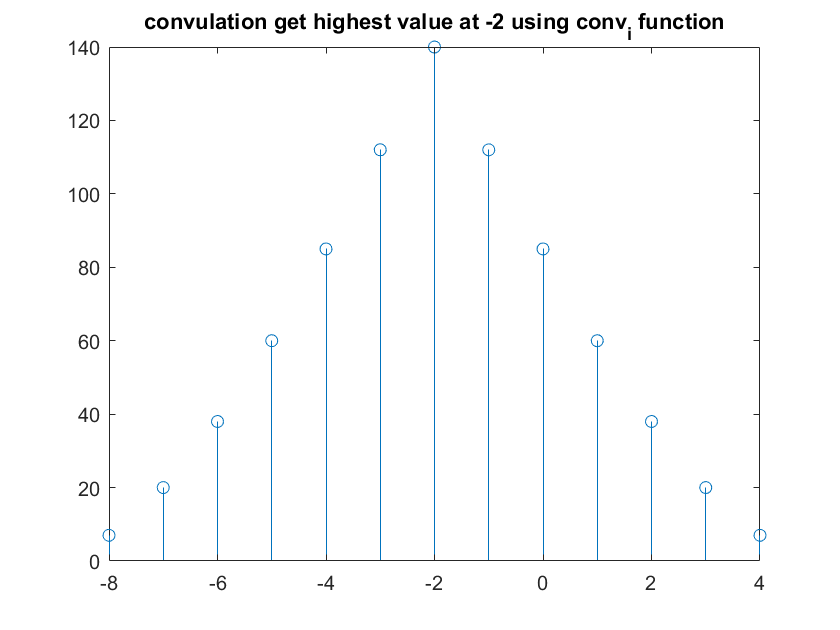

[xc,xcl]=xcorr(x,xc);

% plot
stem(cn,cc)
title('convulation get highest value at -2 using conv_i function')

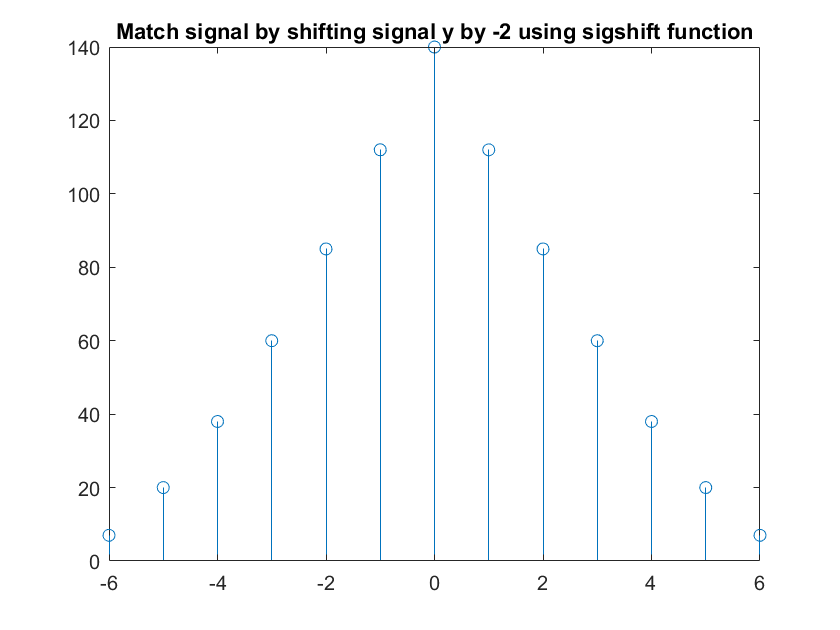

stem(ccsl,ccs)
title('Match signal by shifting signal y by -2 using sigshift function')

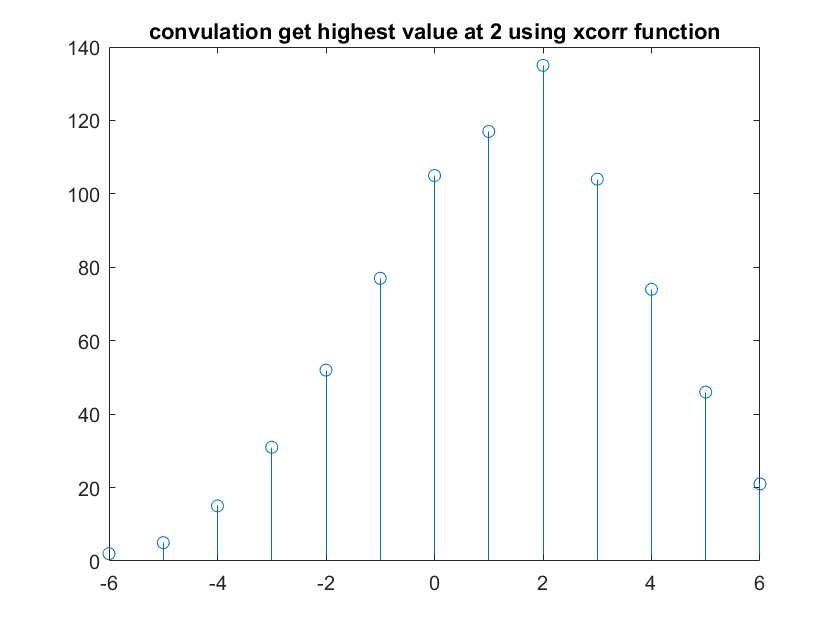


stem(l,c)
title('convulation get highest value at 2 using xcorr function')   

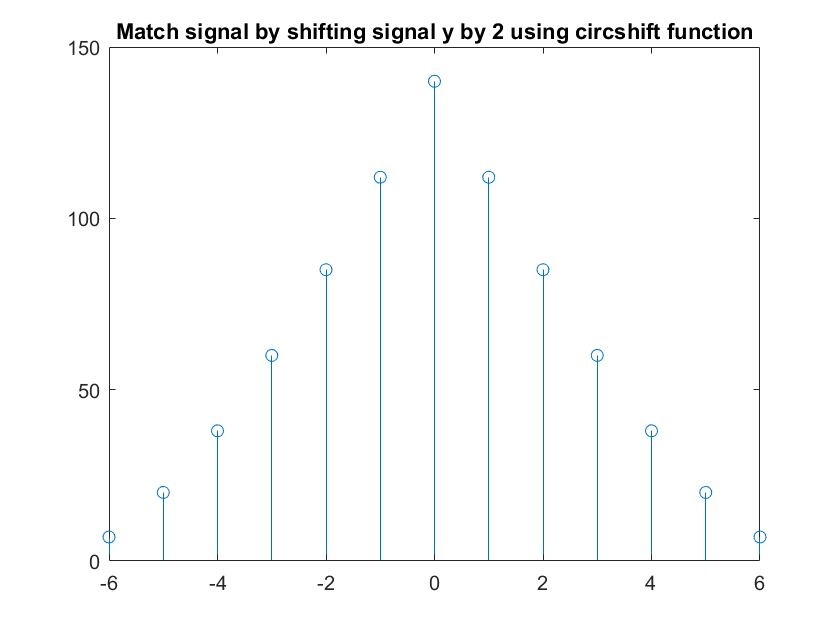

stem(xcl,xc)
title('Match signal by shifting signal y by 2 using circshift function')